# Especies virtuales prueba

----Reading layers----


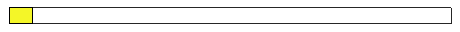

Elapsed time is 11.312030 seconds.


addpath Tool/VirtualSpeciesFunctions/
addpath Tool/
layerfolder = "Capas/Capas_SouthAmerica_2.5M/"; %route to folder with ambiental data
Dimensions = ReadLayers(layerfolder);

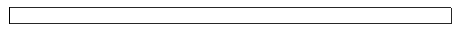

alpha:2


Samples:10


Occupation:0.1


close all

% Occupation = [0.1 1];
% Samples = [10 50];
alpha = 2; 
Occupation = 0.1:0.2:0.7;            % Ocupacion terreno
% Samples = [1000];          % Número de puntos 
Samples = [10 50 100 1000];          % Número de puntos 
% alpha = 0 : 0.25 : 1;              % Forma de muestreo

[OccupExp, SampExp, alpExp] = meshgrid(Occupation, Samples, alpha);
OccupExp = OccupExp(:);
SampExp = SampExp(:);
alpExp = alpExp(:);

% generacion de los puntos iniciales
N = 500;
Size = Dimensions.Dimensions(2);

p = sobolset(Size);
p = scramble(p, 'MatousekAffineOwen');
Points = net(p, N);

p = sobolset(Size);
p = scramble(p, 'MatousekAffineOwen');
Coeffs = net(p, N);

showVirtual = false;
showModel = false;

Roc = zeros(length(SampExp), N); 
AreaMetric = zeros(length(SampExp), N);
DistanceMetric = zeros(length(SampExp), N);


tic
InfoInitialPoint = cell(N, 1);

for j = 1 : N
    %initial point definition
    progressbar(j/N)
    InfoInitialPoint{j} = InitialPoint(Dimensions, Points(j, :)', Coeffs(j, :)');

%     parfor i = 1 : length(SampExp)
    for i = 1 : length(SampExp)
        disp("alpha:" + alpExp(i))
        disp("Samples:" + SampExp(i))
        disp("Occupation:" + OccupExp(i))
        disp(" ")
        
        MapInfo = VirtualSpecies(Dimensions, InfoInitialPoint{j}, OccupExp(i), showVirtual);
        NicheMap = MapInfo.Map;
        T = samplingVS(Dimensions, MapInfo, SampExp(i), alpExp(i), showVirtual, 'GenSP', true, true);
        data = bnm_prep(T, Dimensions, false, 0.7);
        % modeling, save Metric
        data = bnm_modeling(data, '', showModel);   
        ModelMap = data.Map;
        VectorMet = MapMetric(NicheMap, ModelMap, false);
        AreaMetric(i, j) = VectorMet(1);
        DistanceMetric(i, j) = VectorMet(2);
        %% SACAR LA ROC %%
        Roc(i, j) = data.Roc;
%         drawnow
%         close all
    end
end

FinalTime = toc;
save("Test_KRidge_SA_25_NoAlpha_6", "OccupExp", "SampExp", "alpExp", "DistanceMetric", "AreaMetric", "Points", "Coeffs", "Roc","FinalTime")
% save("Test1_SA_05_NogAlpha_coor", "Coordenates", '-v7.3')